clear

options = odeset('RelTol',1e-4, 'Stats','on')

options = struct with fields:
              AbsTol: []
                 BDF: []
              Events: []
         InitialStep: []
            Jacobian: []
           JConstant: []
            JPattern: []
                Mass: []
        MassSingular: []
            MaxOrder: []
             MaxStep: []
         NonNegative: []
         NormControl: []
           OutputFcn: []
           OutputSel: []
              Refine: []
              RelTol: 1.0000e-04
               Stats: 'on'
          Vectorized: []
    MStateDependence: []
           MvPattern: []
        InitialSlope: []


# Уточняющие опции

#### Уравнение Эйлера:


$$\ddot x+\frac{\dot x}{t}+100\frac{x}{t^2}=0,$$
 

где $t \in [1, 100], x(1)=1, \dot x(1)=1.$

Уравнение Эйлера, записанное в виде функции MATLAB:

Решение:

Start_cond = [1; 1];   % Начальные условия
t_interval = [1 5];    % Интервал рассчитываемого времени

2 переменных опции

options_r0  = odeset('Refine', 1, 'Stats','on');
options_r   = odeset('Refine', 100, 'Stats','on');

Решение с `Refine = 1`

[t_r0, X_r0]= ode45(@euler_eqn, t_interval, Start_cond, options_r0); 

35 successful steps
0 failed attempts
211 function evaluations


�

Решение с `Refine = 100`

[t_r, X_r]  = ode45(@euler_eqn, t_interval, Start_cond, options_r);

35 successful steps
0 failed attempts
211 function evaluations


Постройка графиков:

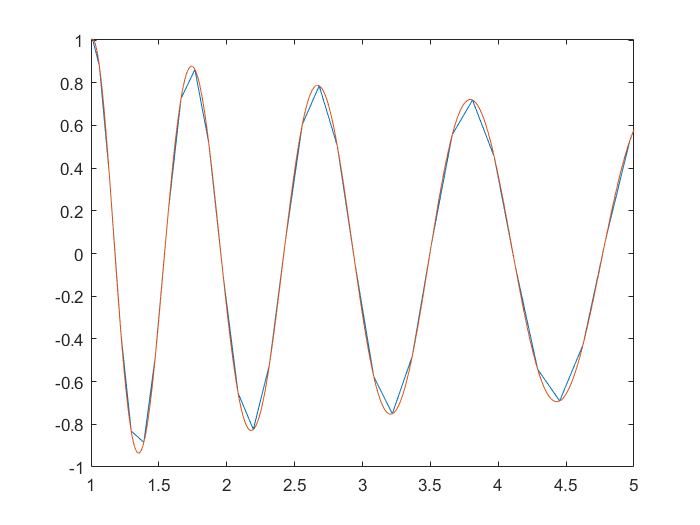

plot(t_r0,X_r0(:,1))
hold on
plot(t_r,X_r(:,1))
hold off

# Определение решения в желаемых точках

**Запишем решение в виде структуры MATLAB:**

Solution = ode45(@euler_eqn, t_interval, Start_cond)

Solution = struct with fields:
     solver: 'ode45'
    extdata: [1×1 struct]
          x: [1×36 double]
          y: [2×36 double]
      stats: [1×1 struct]
      idata: [1×1 struct]


Зададим вектор желаемых точек:

points = 1.1:0.01:4.2;

Получим решение на векторе:

Eval_result = deval(Solution, points)

Eval_result =     0.6478    0.5732    0.4942    0.4114    0.3257    0.2379    0.1488    0.0592   -0.0301   -0.1184   -0.2049   -0.2891   -0.3701   -0.4476   -0.5208   -0.5892   -0.6523   -0.7098   -0.7613   -0.8064   -0.8450   -0.8769   -0.9019   -0.9198   -0.9308   -0.9347   -0.9316   -0.9218   -0.9053   -0.8824   -0.8534   -0.8185   -0.7781   -0.7326   -0.6822   -0.6274   -0.5688   -0.5066   -0.4414   -0.3737   -0.3039   -0.2326   -0.1603   -0.0873   -0.0143    0.0583    0.1301    0.2007    0.2695    0.3362
   -7.2125   -7.6977   -8.1054   -8.4343   -8.6838   -8.8538   -8.9447   -8.9576   -8.8942   -8.7569   -8.5486   -8.2731   -7.9345   -7.5373   -7.0857   -6.5847   -6.0396   -5.4554   -4.8377   -4.1921   -3.5242   -2.8393   -2.1432   -1.4416   -0.7399   -0.0433    0.6434    1.3153    1.9680    2.5972    3.1991    3.7700    4.3062    4.8047    5.2628    5.6781    6.0488    6.3734    6.6508    6.8800    7.0605    7.1919    7.2740    7.3074    7.2928    7.2311    7.1239    6.9729    6

Визуализируем результат

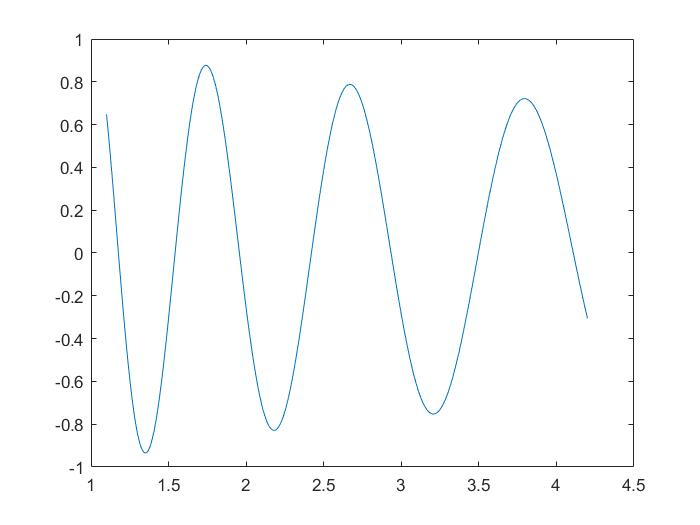

plot(points, Eval_result(1,:))

# Управление шагом решателя

**Зададим опции: **без ограничения шага и с ограничением:

options_ms0 = odeset('Stats','on');
options_ms = odeset('MaxStep',1e-03, 'InitialStep', 1e-04, 'Stats','on');

Получим решения:

[t_ms0, X_ms0] = ode23(@euler_eqn, t_interval, Start_cond, options_ms0);

116 successful steps
7 failed attempts
370 function evaluations


[t_ms, X_ms] = ode23(@euler_eqn, t_interval, Start_cond, options_ms);

4002 successful steps
0 failed attempts
12007 function evaluations


Определим величину шага на каждой итерации:

dt_ms = [t_ms(2:end);0] - t_ms

dt_ms =     0.1000
    0.5000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000


# А нужно ли ограничивать шаг?

**Сравним 3 ситуации: **оценим время вычисления

- Ситуация №1: ограничение шага через **'MaxStep'**

- Ситуация №2: уточнение через `'Refine'`

- Ситуация №3: увеличение точности через  `'AbsTol'` и `'RelTol'`

**Ситуация №1**

options_1 = odeset('MaxStep',1e-05, 'Stats','on');
tic
[t_1, X_1] = ode23(@euler_eqn, t_interval, Start_cond, options_1);

400000 successful steps
0 failed attempts
1.2e+06 function evaluations


toc

Elapsed time is 4.001657 seconds.


**Ситуация №2**

options_2 = odeset('Refine',4000, 'Stats','on');
tic
[t_2, X_2] = ode23(@euler_eqn, t_interval, Start_cond, options_2);

116 successful steps
7 failed attempts
370 function evaluations


toc

Elapsed time is 0.052757 seconds.


**Ситуация №3**

options_3 = odeset('AbsTol',3.8e-17,'RelTol', 3.8e-14, 'Stats','on');
tic
[t_3, X_3] = ode23(@euler_eqn, t_interval, Start_cond, options_3);

400604 successful steps
0 failed attempts
1.20181e+06 function evaluations


toc

Elapsed time is 3.921235 seconds.
